%       ***PROGETTO LAB AUTOMATICA***


clear all;
clc;
close all;
addpath(['..',filesep,'modelli']) % aggiungi cartella path
addpath(['..',filesep,'identificazione'])
addpath(['..']) ;

%parametri da inserire
nome_gruppo='Quebec';
sistema_op='Win'; % a scelta fra 'Win' o 'Mac'


% creo il sistema da controllare
% system è lo scara da controllare.
% rigid_robot è il modello che non considera l'elasticità. Si può (non
% obligatoriamente) utilizzare per fornire la coppia precalcolata
[system,rigid_robot]=getRoboticSystem(nome_gruppo);

% uso la funzione compilata per il calcolo della dinamica (arriverà anche
% per mac)
if strcmp(sistema_op,'Mac')==true
    system.setForwardDynamics(@fdCodegenMac);
elseif strcmp(sistema_op,'Win')==true
    system.setForwardDynamics(@fdCodegen_ubuntu);
end

%parametri di output del modello
n_output=length(system.getOutputName);
for io=1:n_output
    fprintf('output %d: %s\n',io,system.getOutputName{io});
end

output 1: position_1
output 2: position_2
output 3: velocity_1
output 4: velocity_2



%parametri di input del modello
n_input=system.getInputNumber;
u_max=system.getUMax;
for ii=1:n_input
    fprintf('input %d: %s. valore massimo coppia %f\n',ii,system.getInputName{ii},u_max(ii));
end

input 1: torque_1. valore massimo coppia 150.000000
input 2: torque_2. valore massimo coppia 150.000000



% tempo di campionamento 1ms
st=system.getSamplingPeriod;

% definisco il sistema di controllo
cs=ControlledSystem(system);

giunto='1'; %a scelta fra giunto '1' o giunto '2' 

## SEGNALE DI IDENTIFICAZIONE

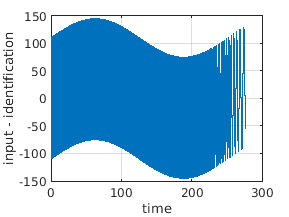

% %parametri da impostare:
% con_portante=true; % possibilità di scelta segnale chirp con portante o senza portante
% lunghezza_prova=1; %lunghezza segnale di identificazione in secondi, nb nel caso si 
% %usi l'identificazione con la portante per modificare la lunghezza della
% %prova bisogna cambiare il valore della pulsazione della portante
% 
% 
% %generazione del segnale di eccitazione
% if con_portante==0
%     t=(0:st:lunghezza_prova)'; 
%     w0=10; %rad/s, pulsazione iniziale chirp
%     w1=pi/st; %3140 rad/s, pulazione finale chirp
%     control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
%     ampliezza_identificazione=150; %max 150
%     control_action=control_action_identificazione*ampliezza_identificazione;
% else
    omega_portante=0.025; 
    ampiezza_portante=35;
    T_portante=2*pi/omega_portante; % periodo della portante
    t=(0:st:(1.1*T_portante))'; %tempo esperimento
    portante=ampiezza_portante*sin(omega_portante*t);
    w0=1; 
    w1=3000; %3140 rad/s
%     control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi,'logarithmic');
    control_action_identificazione = chirp(t,w1/2/pi,t(end),w0/2/pi,'logarithmic');
    ampliezza_identificazione=110;
    control_action=portante+ control_action_identificazione*ampliezza_identificazione;
% end

figure()
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on


%ampiezza del chirp maggiore della portante
if strcmp(giunto, '1')==true
    tau=[control_action 0*ones(length(t),1)];

elseif strcmp(giunto, '2')==true
    tau=[0*ones(length(t),1) control_action];   
end

## prova in anello aperto (simulazione sistema con ingresso eccitante)

output=zeros(length(t),n_output);

for it=1:length(t)
    output(it,:)=cs.openloop(tau(it,:)');
end

Unrecognized function or variable 'fdCodegen_win'.

Error in ElasticRoboticSystem>@(q,qd,tau,payload)forwardDynamics(q,qd,tau,payload,obj.ig)

Error in ElasticRoboticSystem/stateFunction

Error in MechanicalSystem/odeSolver (line 104)
                k_1 = obj.stateFunction(obj.x,u,t);

Error in MechanicalSystem/updateState (line 49)
            


pos1=output(:,1);
pos2=output(:,2);

vel1=output(:,3);
vel2=output(:,4);

tau1=tau(:,1);
tau2=tau(:,2);

% grafico tutti i risultati
figure
tiledlayout(3,2)
nexttile
plot(t,pos1)
grid on
xlabel('t');
ylabel('pos 1')

nexttile
plot(t,pos2)
grid on
xlabel('t');
ylabel('pos 2')

nexttile
plot(t,vel1)
grid on
xlabel('t');
ylabel('vel 1')

nexttile
plot(t,vel2)
grid on
xlabel('t');
ylabel('vel 2')

nexttile
plot(t,tau1)
grid on
xlabel('t');
ylabel('torque 1')

nexttile
plot(t,tau2)
grid on
xlabel('t');
ylabel('torque 2')

## IDENTIFICAZIONE

if strcmp(giunto, '1')==true
    identification=iddata(vel1,tau1,st);

elseif strcmp(giunto, '2')==true
    identification=iddata(vel2,tau2,st);   
end

freq_resp_ident = spafdr(identification); %estimates the input-to-output frequency response G(ω)

figure()
bode(freq_resp_ident)
hold on
plot(w0*[1 1],ylim,'--r')
hold off

## stima modello con peso sulla frequenza

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=100;   %frequenza iniziale di interesse
wpeso1=300; %frequenza finale di interesse
peso(freq_resp_ident.Frequency<wpeso0)=1e-5; %basso peso=poca importanza
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(freq_resp_ident,3,opts);
modello_discreto = ssest(freq_resp_ident,3,'Ts',st,opts);

% grafico
figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo,modello_discreto, bode_opts)
xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
hold off
grid on
xlim([1e-1 1e4])
legend('Identification','Modello continuo','Modello discreto')

## VALIDAZIONE CON PORTANTE

## validazione multisine

%segnale: portante+multisin
omega_portante=0.025;
ampiezza_port=35;
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_port*sin(omega_portante*t);

#### Multisinusoidi:

Scelgo le sinusoidi come un vettore composto da due pacchi di sinusoidi


omega=sort([logspace(log10(1),log10(3000),30)' ; ...
           logspace(log10(70),log10(1000),30)']);


arrotondo a dei multipli della portante

omega=round(omega/omega_portante)*omega_portante; % arrotondo per avere le omega multiple della portante
omega=unique(omega); %scarto eventuali doppioni

multisine_signal=zeros(length(t),1);%Creo il segnale come somma di sinusoidi (qui suppongo ampiezza costante per ogni pulsazione, nulla mi impedisce di fare diversamente)
for idx=1:length(omega)
    multisine_signal=multisine_signal+sin(omega(idx)*t);
end
max_applitude=150; %Impongo che l'ampiezza del segnale sia quella desiderata
multisine_signal=multisine_signal/max(multisine_signal)*max_applitude;
control_action=portante+ multisine_signal; %Sommo i due segnali

control_action_coef=fourierCoefficients(t,control_action,omega_portante,omega);%Calcolo i coefficienti di Fourier dell'ingresso

figure()
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

Simulo il sistema


if strcmp(giunto, '1')==true
    tau=[control_action 0*ones(length(t),1)];

elseif strcmp(giunto, '2')==true
    tau=[0*ones(length(t),1) control_action];   
end
process_output_vali=zeros(length(t),n_output);
cs.initialize
for idx=1:length(t)
    process_output_vali(idx,:)=cs.openloop(tau(idx,:)');
end



pos1=process_output_vali(:,1);
pos2=process_output_vali(:,2);

vel1=process_output_vali(:,3);
vel2=process_output_vali(:,4);

tau1=tau(:,1);
tau2=tau(:,2);

% grafico tutti i risultati
figure
tiledlayout(3,2)
nexttile
plot(t,pos1)
grid on
xlabel('t');
ylabel('pos 1')

nexttile
plot(t,pos2)
grid on
xlabel('t');
ylabel('pos 2')

nexttile
plot(t,vel1)
grid on
xlabel('t');
ylabel('vel 1')

nexttile
plot(t,vel2)
grid on
xlabel('t');
ylabel('vel 2')

nexttile
plot(t,tau1)
grid on
xlabel('t');
ylabel('torque 1')

nexttile
plot(t,tau2)
grid on
xlabel('t');
ylabel('torque 2')


if strcmp(giunto, '1')==true
process_output_coef=fourierCoefficients(t,vel1,omega_portante,omega);

elseif strcmp(giunto, '2')==true
process_output_coef=fourierCoefficients(t,vel2,omega_portante,omega);  
end

freq_resp_validazione=idfrd(process_output_coef./control_action_coef,omega,st); % Y(i*omega)/U(i*omega)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure
bodeplot(freq_resp_validazione,freq_resp_ident, bode_opts);
legend('validazione','ident');
grid on
hold on

Diagramma di Bode Validazione


figure

h=bodeplot(freq_resp_validazione,'-g',freq_resp_ident, bode_opts);
showConfidence(h,3)
hold on
bode(modello_continuo,modello_discreto, bode_opts)
xlim([omega(1) omega(end)])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
grid on

legend('Validazione','identificazione','Modello continuo','Modello discreto')
